rng('default'); % For reproducibility

A chip design organizes all the information about the chip relevant to the optimization. Since we're interested in designs with particular structure, we can generate artificial data for now. The `generate_design.m `script generates a random design with a specified number of instances and macros. For example, to create a design with 1000 instances, 10 of which are macro cells, enter:

n      = 1000;
n_mac  = 10;
design = generate_design(n, n_mac)

design = struct with fields:
              R: [1×1 struct]
    utilization: 0.5126
             x0: [1000×1 double]
             y0: [1000×1 double]
             dx: [1000×1 double]
             dy: [1000×1 double]
        netlist: {500×1 cell}
         groups: {10×1 cell}
        mac_idx: [1 2 3 4 5 6 7 8 9 10]
        std_idx: [11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 79 80 81 82 83 84 85 86 87 … ]
        n_cells: 1000
         n_nets: 500
       n_groups: 10
          n_mac: 10
          n_std: 990


Note: In this implementation the coordinates of a cell refer to it's center, which is also used as the pin location to reduce unnecessary complexity. This means that the lower left corner of a cell is `(x - 0.50*dx, y - 0.50*dy) etc.`

The majority of the functionality is in the `Placer.m` file`.` To create a `Placer` object:

p = Placer()

p =   Placer with properties:

             design: [1×1 struct]
               nets: {500×1 cell}
               grid: [1×1 struct]
              masks: {1000×1 cell}
             charge: [1000×1 double]
            density: [128×128 double]
          potential: [128×128 double]
              field: [1×1 struct]
               xind: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 79 … ]
               yind: [1001 1002 1003 1004 1005 1006 1007 1008 1009 1010 1011 1012 1013 1014 1015 1016 1017 1018 1019 1020 1021 1022 1023 1024 1025 1026 1027 1028 1029 1030 1031 1032 1033 1034 1035 1036 1037 1038 1039 1040 1041 1042 1043 1044 1045 … ]
                 mu: 1
    grid_resolution: 128
      default_n_mac: 10
     default_n_cell: 1000


When a Placer object is created it loads the design data, creates a collection of Nets to model the design's netlist, and generates an artificial grid based on the value of `grid_resolution.` Each net is an instance of an object defined in `Net.m`. Each net can retrieve the coordinates of cells belonging to it, compute the smooth half-perimeter wire length (with derivatives), or compute the coordinate variances (with derivatives). For example,

net = p.nets{1}

net =   Net with properties:

              id: 1
           cells: [8 835 451 286 875 714 460 345 379 500 988 939 945 600 901 217 433 878 662 504 382 103 497 181 326 685 604 316 79 411 350 923 727 902 206 944 858 671 269]
        net_size: 39
    smooth_param: 256


net.locate_pins(p.design.x0, p.design.y0)

ans = struct with fields:
    x: [39×1 double]
    y: [39×1 double]


net.WAWL(p.design.x0, p.design.y0)

ans = 3.1076e+04

At this point, the density is computed at the intial point specified in the design.  This produces a `p.grid.nx` by `p.grid.ny` array stored in `p.density.`

For convenience, there is a method to visualize the heatmap of any `grid_resolution x grid_resolution` matrix. For example, we can visualize the initial density as follows

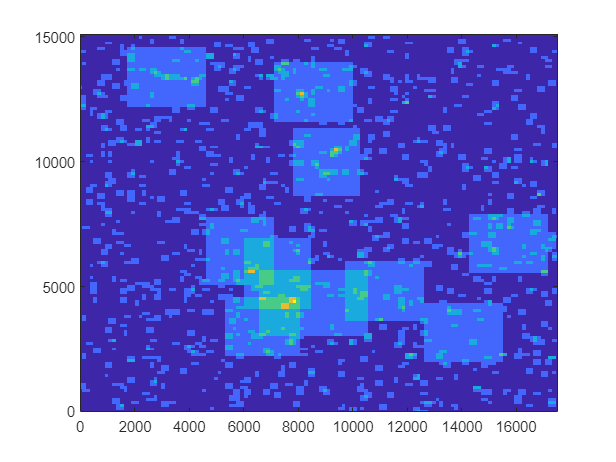

ans =   Image with properties:

           CData: [128×128 double]
    CDataMapping: 'scaled'

  Show all properties


p.plot_heatmap(p.density)

Given any density map D, the resulting electrostatic quantities can be computed

- The potential map P (same dimensions as D)

- The electrosatic field F, with two maps F.x and F.y (each same dimensions as D)

- The total electrostatic energy E (scalar)

The potential and field maps can also be visualized

[P, F, E] = p.compute_electrostatics(p.density)

P =  -145.2353 -145.1145 -144.8696 -144.4934 -143.9746 -143.2958 -142.4433 -141.4372 -140.4470 -140.0642 -140.2051 -140.1452 -139.8448 -139.3748 -138.7582 -138.0147 -137.1520 -136.1789 -135.1627 -134.2911 -133.5835 -132.8909 -132.1823 -131.4965 -130.8548 -130.2333 -129.5945 -128.9217 -128.2074 -127.4479 -126.6397 -125.8380 -125.2129 -124.7644 -124.3231 -123.8392 -123.3272 -122.8079 -122.3059 -121.8491 -121.4721 -121.2111 -121.0893 -121.1062 -121.2401 -121.4587 -121.7348 -122.0458 -122.3834 -122.7536
 -144.9334 -144.8160 -144.5775 -144.2140 -143.7102 -143.0554 -142.1881 -141.1171 -140.3789 -140.0544 -140.0899 -139.9444 -139.5935 -139.0952 -138.4626 -137.7112 -136.8444 -135.8361 -134.6655 -133.7737 -133.1811 -132.4905 -131.7362 -131.0089 -130.4123 -129.8331 -129.2078 -128.5412 -127.8305 -127.0781 -126.2466 -125.3078 -124.6831 -124.3712 -123.9482 -123.4464 -122.9126 -122.3671 -121.8380 -121.3479 -120.9337 -120.6481 -120.5268 -120.5675 -120.7348 -120.9840 -121.2806 -121.5995 -121.9293 -122

F = struct with fields:
    x: [128×128 double]
    y: [128×128 double]


E = 3.3098e+05

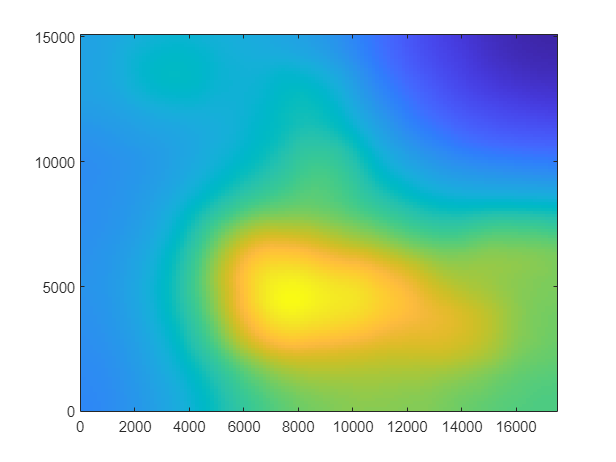

ans =   Image with properties:

           CData: [128×128 double]
    CDataMapping: 'scaled'

  Show all properties


figure;
p.plot_heatmap(P)

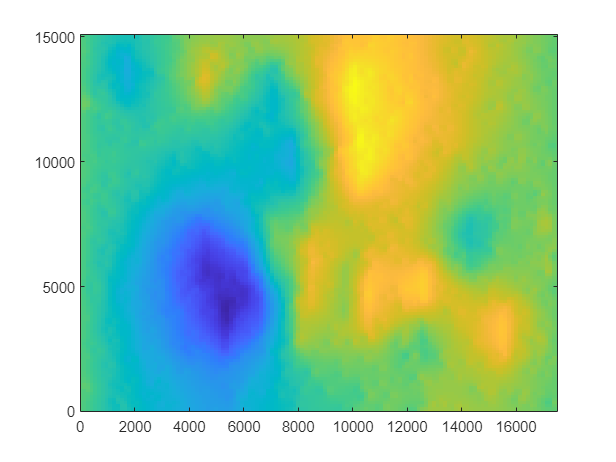

ans =   Image with properties:

           CData: [128×128 double]
    CDataMapping: 'scaled'

  Show all properties


p.plot_heatmap(F.x)

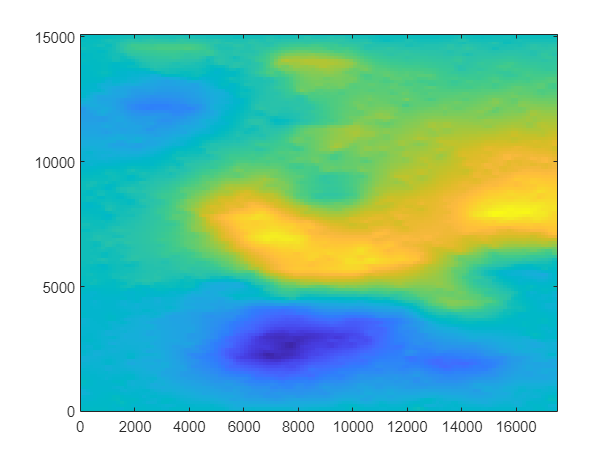

ans =   Image with properties:

           CData: [128×128 double]
    CDataMapping: 'scaled'

  Show all properties


p.plot_heatmap(F.y)

We can plot the cells over the potential to see how they're related:

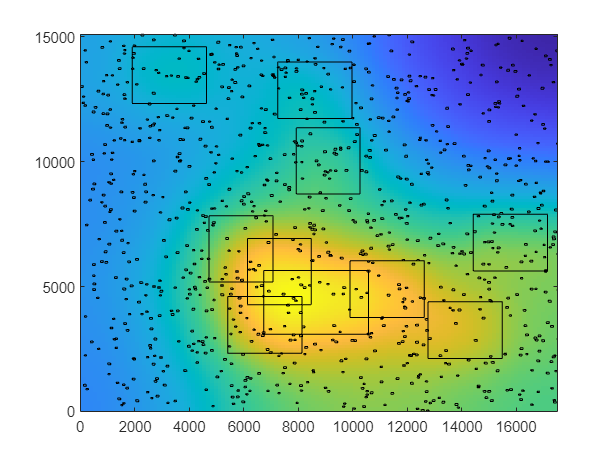

p.plot_heatmap(P); hold on;
p.plot_cells(p.design.x0, p.design.y0, 1:p.design.n_cells)

The evaluate method computes the function value and gradient of the penalty function `f(z) = W(z) + mu*E(z) `based on a given placement `z = [x; y]. `The function W is an approximation of the wire length, and could be the weighted-average half-perimeter wire length or the variance of the net coordinates, both are available. At the moment it is using the net coordinate variances.

[f, g] = p.evaluate(p.design.z0)

f = 2.2118e+10

g = 1.0e+04 *

    0.9118
    0.4650
    0.0865
   -0.3579
   -0.0779
    0.1400
    0.1083
    0.0069
   -0.1867
    0.2017


There is also a clearance function `p.clearance(x, y, cells)` that computes the minimum clearance between any pair of cells in the list provided. This is computed by looking at the maxium of the width of the strip that could fit horizontally/vertically between the boundaries of each pair of cells. This value is positive if there is no overlap, zero if they are touching, and negative if they intersect. The minimum of all pairwise clearances is the overall clearance, and should provide a function whos zero level set corresponds to collision. For example, macros 1 through  6 are not overlapping, and their clearance is positive:

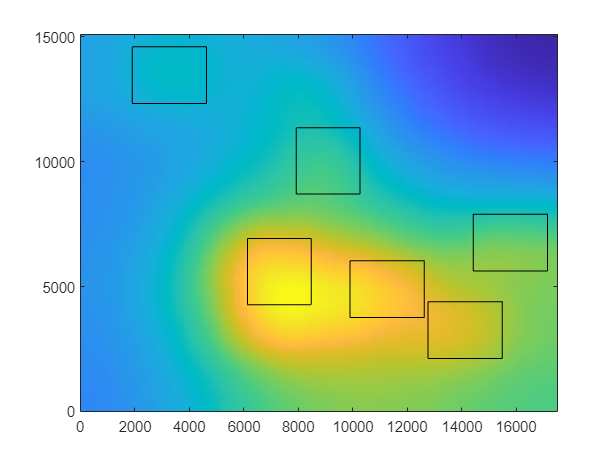

p.plot_heatmap(P); hold on;
p.plot_cells(p.design.x0, p.design.y0, 1:6)

p.compute_clearance(p.design.x0, p.design.y0, 1:6)

ans = 133

However, macros 3 and 7 overlap, so if 7 is added in the clearance is negative

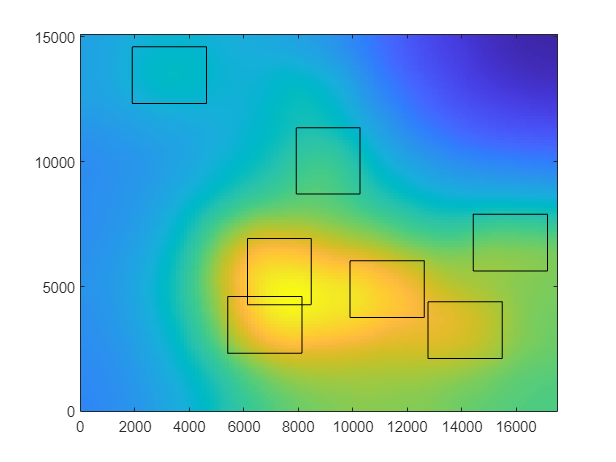

p.plot_heatmap(P); hold on;
p.plot_cells(p.design.x0, p.design.y0, 1:7)

p.compute_clearance(p.design.x0, p.design.y0, 1:7)

ans = -323

Suppose we want to look at a specific net, the cells in it, and the negative of the gradient on those cells. This can be done as follows:

net_index = 13;
cells = p.nets{net_index}.cells

cells =    772   675   357   943   219    82   284   296   542     9   446    76   100   442   616   755   920   673   859


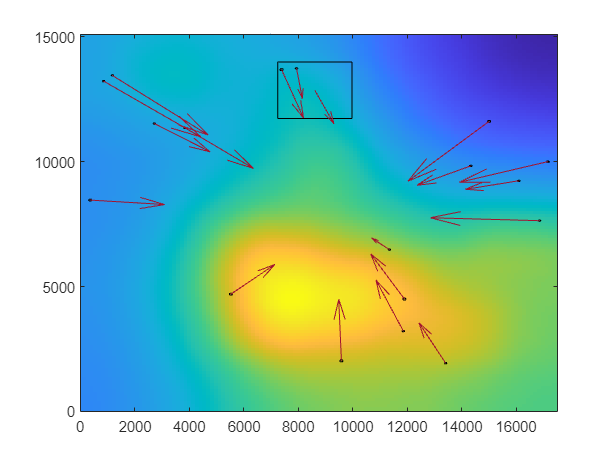

p.plot_heatmap(P);
p.plot_cells(p.design.x0, p.design.y0, cells);  hold on
quiver(p.design.x0(cells), p.design.y0(cells), -g(cells), -g(p.design.n_cells + cells))

Note that the indices for the y coordinates of g are shifted by the number of cells since `g = [gx; gy]`